# **변경사항**

## 2022.4.8

## 2022.1.15

첫 배포

- `fireRateMaker.m` : `summary_examples_firing_rate.mlx`의 코드를 내장 함수로 가지는 class. `Channel` objet를 입력하면 firing rate histogram을 생성. 특정 이벤트 기준으로 centering하지 않기 때문에 Peri-stimulus time histogram(PSTH)가 아니라 그냥 time histogram(TH) 임. 

- `timeVaryingHeatmap.m`** : **여러 `channel` object를 입력하면 내부적으로 `fireRateMaker` object를 생성하고 time-varying heatmap을 만들거나 동영상 파일로 저장하는 class. 입력된 모든 `channel`의 [시작시간, 종료 시간]의 교집합을 시간 구간으로 함.    

                  *  heatmap 관련 옵션 수정 시, 이 파일의 `makeTimeVaryingHeatmap`, `RecordTimeVaryingHeatmap` 함수를 수정하면 됨

# **주의**

## 경로 추가 관련

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

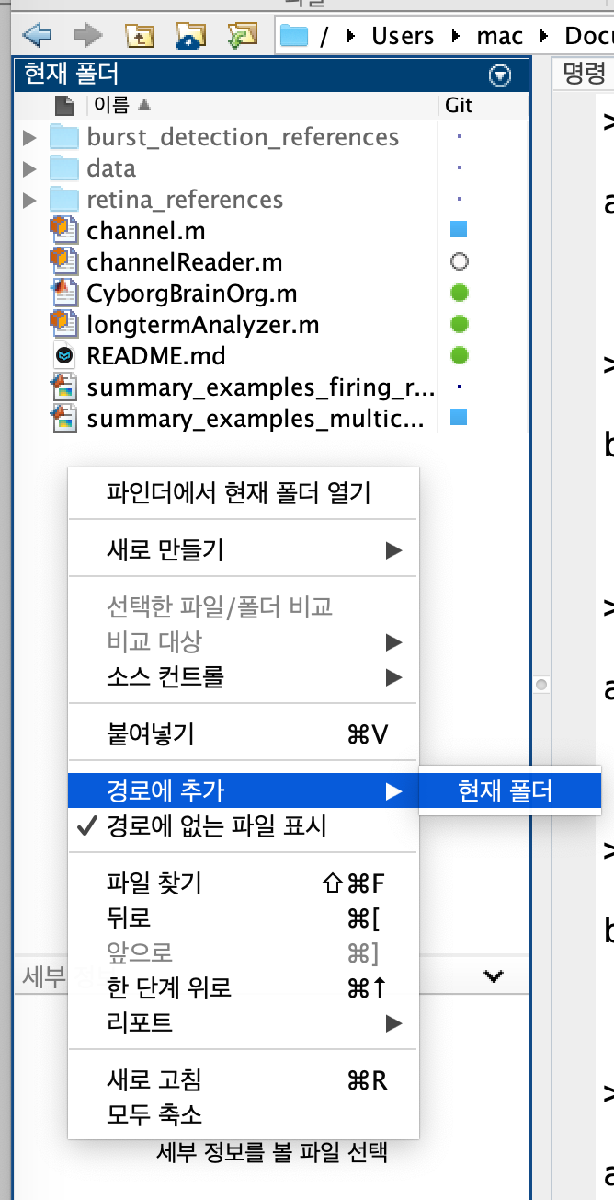

## **1.multi-pixel retina data 불러와 channel object 만들기**

**1.1. 파일 전체를 읽어오기**

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                            filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("./data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 소요시간 측정. 적지 않은 시간 소요됨

경과 시간은 62.088876초입니다.


**1.2. 읽어온 파일에서 모든 채널 데이터를 가져와 channel object의 list로 만들기**

#### `(method) channelReader.readManyChannelsFromFile()`

`readManyChannelsFromFile`은 `channel` 오브젝트의 list를 반환. 개별 `channel` 오브젝트는 {채널번호}로 인덱싱하여 얻을 수 있음

**    input:**

- `organoid`**:** organoid 번호 (관리를 위한 번호, 제한 없음) 

- `pixel numbers`: pixel 번호 array

- `month`: month. 나중에 month별로 종합할 때 사용됨 (관리를 위한 번호, 제한 없음)

%                                 organoid, pixel numbers, month
pixels = reader.readManyChannelsFromFile(1, 1)

Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73

pixels =   Map - 속성 있음:

        Count: 64
      KeyType: double
    ValueType: any


## **2. timeVaryingHeatmap object 생성 후 픽셀 입력 **

#### (class) `timeVaryingHeatmap`

`timeVaryingHeatmap `class는 pixel이 2차원 정방형 배열로 되어 있다고 가정함.. 오브젝트 생성 시 행, 열 개수를 입력.

**    input:**

- `nrow` : pixel 배열의 행 개수

- `ncol` : pixel 배열의 열 개수

#### (method) `timeVaryingHeatmap.addPixel()`

**    input:**

- `channel `: channel object. 여러개 입력 가능. 여러 channel을 한 pixel slot에 입력할 경우, 한 부위에 대한 반복측정으로 간주하고 firing rate는 둘의 평균으로 계산

%                      nrow, ncol
ani = timeVaryingHeatmap(8,8); % timeVaryingHeatmap 오브젝트 생성. pixel들이 8*8 배열로 되어 있다고 가정.
for rowIdx = 1:8
    for colIdx = 1:8
        %  이 pixel의 row번호, column번호, pixel번호
        ani.addPixel(rowIdx,colIdx, pixels( (rowIdx - 1)*8 + colIdx )) %픽셀 번호가 row-wise하게 매겨졌다고 가정하고 timeVaryingHeatmap 오브젝트에 픽셀을 입력
                                         % 여기서는 channel object를 하나만 넣었지만, 두 개 이상을 넣어도 됨. 이 경우 firing rate는 여러 channel의 평균값으로 계산함                          
    end
end


 In the (1, 1)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 2)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 3)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 4)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 5)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 6)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 7)th slot,
Added a channel object with  spikes, timerange 9.814671e+00 - 1.283449e+01(s) 
 Current total number of channels = 1

 In the (1, 

### **3. 모든 픽셀에 일괄적으로 bandpass filter적용하고 spike detection 수행**

개별 channel object에서 사용하던 함수와 똑같은 방법으로 사용

ani.applyBandPassFilter([300,3000])
ani.detectSpikes(5,2,2)


 In the (1, 1)th slot,
number of spikes found : 29

 In the (1, 2)th slot,
number of spikes found : 66

 In the (1, 3)th slot,
number of spikes found : 80

 In the (1, 4)th slot,
number of spikes found : 209

 In the (1, 5)th slot,
number of spikes found : 220

 In the (1, 6)th slot,
number of spikes found : 40

 In the (1, 7)th slot,
number of spikes found : 42

 In the (1, 8)th slot,
number of spikes found : 120

 In the (2, 1)th slot,
number of spikes found : 99

 In the (2, 2)th slot,
number of spikes found : 60

 In the (2, 3)th slot,
number of spikes found : 9

 In the (2, 4)th slot,
number of spikes found : 213

 In the (2, 5)th slot,
number of spikes found : 218

 In the (2, 6)th slot,
number of spikes found : 218

 In the (2, 7)th slot,
number of spikes found : 215

 In the (2, 8)th slot,
number of spikes found : 2

 In the (3, 1)th slot,
number of spikes found : 100

 In the (3, 2)th slot,
number of spikes found : 47

 In the (3, 3)th slot,
number of spikes found : 214

 In 

pixel1 등의 변수명 위에 커서를 올려 보면 bandpass filter, detectSpikes가 적용되었음을 알 수 있다.

pixel1 = pixels{1}

다음 사용 중 오류가 발생함: 인덱싱
containers.Map에서는 '()' 인덱싱만 지원됩니다.

### **4. 모든 픽셀의 spike들에 일괄적으로 cutoff 적용하고, time-varying heatmap 생성**

**(method)**` timeVaryingHeatmap.preProcess`

summary_examples_firing_rate.mlx에서 히스토그램을 그리기 전에 했던 모든 작업을 수행

**    input:**

- `cutoffVal: `특정 측정치 이상의 spike만 고를 때 측정치 기준값

- `binWidth`: firing rate를 측정하는 시간 단위. millisecond.

            % cutoffVal, binWidth(millisecond)
ani.preProcess(5*1e-6, 50) 

**(method)**` timeVaryingHeatmap.makeTimeVaryingHeatmap()`

각 시점의 heatmap을 시간의 흐름에 따라 재생함

**    input:**

- `colormap`: heatmap에서 수치를 색깔로 표현할 때 사용할 colormap

colormap list: https://kr.mathworks.com/help/matlab/ref/colormap.html#d123e146353

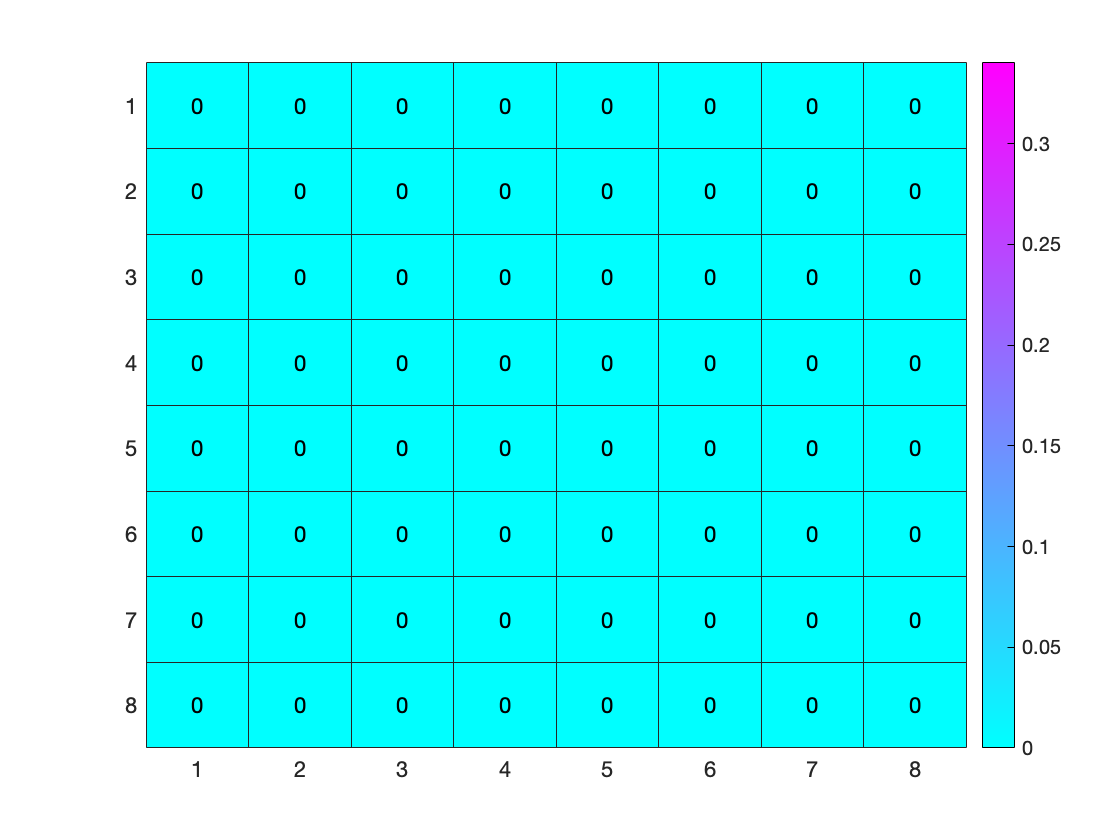

%                         colormap
ani.makeTimeVaryingHeatmap(cool)

### **5. time-varying heatmap을 동영상 파일로 저장**

**(method) **`timeVaryingHeatmap.recordTimeVaryingHeatmap()`

mp4파일로 time-varying heatmap을 저장

**    input:**

- `colormap`

- `framerate`:  초당 프레임 수. 총 frame 수는 원본 데이터 시간 길이 / preProcess의 binWidth 변수에 의해 정해짐. 초당 프레임 수를 늘릴수록 동영상이 빨리 재생됨.  총 100프레임이고 framerate를 5로 하면 100/5 = 20초짜리 동영상이 됨 

ani.recordTimeVaryingHeatmap(cool, "test.mp4", 5)

### **6. 모든 픽셀의 firing rate histogram 그리기**

개별 pixel에 접근한 다음, summary_examples_firing_rate.mlx에서 히스토그램 그릴 때 사용했던 edges, psth 변수, selectedSpikeMs 변수를 가져와 히스토그램 및 raster plot을 그림

#### timeVaryingHeatmap object의 구조:

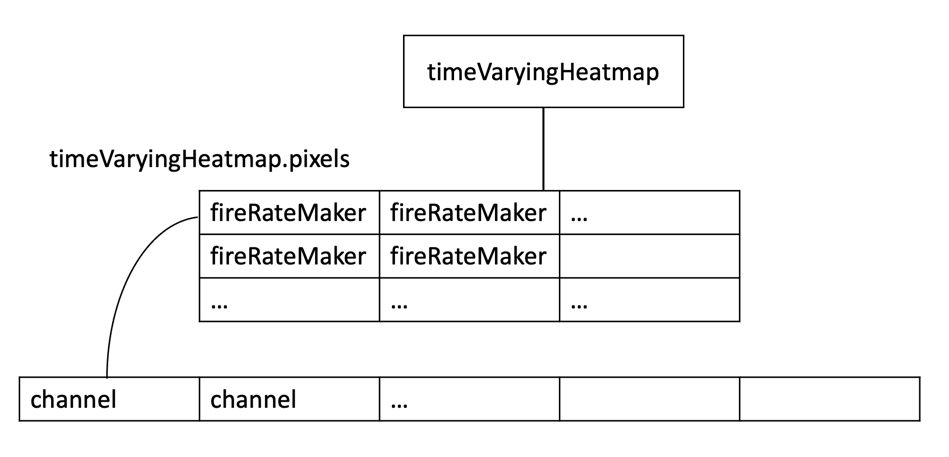

- `timeVaryingHeatmap` object는 `timeVaryingHeatmap.pixels`라는 행렬에 `fireRateMaker` object들을 저장. 

- 각 `fireRateMaker`는 한 개 혹은 여러개의 `channel `object를 저장

- firing rate histogram 정보는 각` fireRateMaker `object에 저장되어 있음

- 하나의 pixel slot에 속한 각 `channel`의 spike timestamp 정보는 `fireRateMaker` object에 selectedMs라는 list로 저장되어 있음

-> `fireRateMaker` object에만 접근하면 histogram, raster plot 다 그릴 수 있음

**그래프 옆의 화살표(figure 창에서 열기)를 누르고 새 창을 전체화면으로 키워야 그래프가 잘 보임**

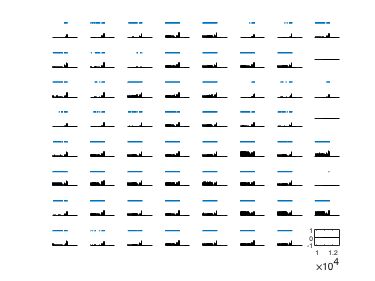

figure;

for rowIdx = 1:8
    for colIdx = 1:8
        pixelNow = ani.pixels{rowIdx, colIdx}; %개별 pixel slot에 접근. fireRateMaker 오브젝트를 얻게 됨
        
        % histogram 정보는 fireRateMaker object에 저장되어 있음
        thNow = pixelNow.th;
        edgesNow = pixelNow.edges;
        subplot(8, 8, (rowIdx - 1)*8 + colIdx )
         bar(edgesNow,thNow); %Plot as a bar graph 

        % spike raster plot 관련 정보는 fireRateMaker object 내의 selectedMs에 저장됨
        selectedSpikesMs = pixelNow.selectedMs{1}; %pixel slot마다 channel을 하나만 넣었으므로 첫 번째 원소만 존재함.
        for i = 1:length(selectedSpikesMs) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
            line([selectedSpikesMs(i) selectedSpikesMs(i)], [0.9, 1])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
        end
        
    end
end

%그래프 하나 빼고 축 전부 제거
t = get(get(gcf, 'Children'), 'XAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
t = get(get(gcf, 'Children'), 'YAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
set(get(gcf, 'Children'), 'Color', 'none')

## 7. section 6의 히스토그램이 제대로 그려졌는지 확인하기 위해, 4번째 pixel의 히스토그램을 class 없이 그려 보기

data1 = reader.readSingleChannelFromFile(1, 4, 1);
data1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
data1.detectSpikes(5,2,2);
data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 5*1e-6; % apply the cutdoff. the result looks like (true, true, false, true, false,...)
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean); %apply the boolean and get the selected spikes
data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000; %milisecond 단위

edges = [data1.startTime*1000: 50: data1.endTimeApprox*1000]; %시작점 : 구간길이 : 끝점
th = zeros(length(edges),1)'; %Initialize the PSTH with zeros
th = th + histc(data1SelectedMs,edges);
th = th / 50; %firing rate

figure
bar(edges,th); %Plot PSTH as a bar graph 
xlim([min(edges), max(edges)]);%Set limits of X-axis 
xlabel('Time (sec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

## 8. **모든 픽셀의 filtered signal trace 그리기**

signal data는 fireRateMaker object에는 저장되지 않고, channel object까지 접근해야 얻을 수 있음

**그래프 옆의 화살표(figure 창에서 열기)를 누르고 새 창을 전체화면으로 키워야 그래프가 잘 보임**


figure;

for rowIdx = 1:8
    for colIdx = 1:8
        channelNow = ani.pixels{rowIdx, colIdx}.channels{1}; %channel object를 각 slot마다 하나씩만 넣었으므로, 첫 번째 channel만 사용해도 됨
        
        subplot(8,8,(rowIdx - 1) * 8 + colIdx )
        plot(channelNow.t, channelNow.filtered); %matlab 기본 plot 함수 사용

        ylim([-6,6]*1e-4);%ylim 조절 가능

        end
end
%그래프 하나 빼고 축 전부 제거
t = get(get(gcf, 'Children'), 'XAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
t = get(get(gcf, 'Children'), 'YAxis');
t = t(2:end);
set([t{:}], 'Visible', 'off')
set(get(gcf, 'Children'), 'Color', 'none')